# Lab 05

## Syed  Muhammad Asad Ali

### sa09475

#### Task 1

**(a) **- The order of inputs doesn’t matter, we can see that by switching two signals u and v, the output  of convolution was same in both cases. Hence convolution is commutative. 

**(b)** - The convolution output shows the area when both the graphs are overlapping. 1 graph shifts  horizontally against the other graph and the area below both of them is known as the  convolution.

#### Task 2

**(a)** - The length of the output signal from the convolution sum is nearly the sum of the lengths of the  individual inputs. Since the individual inputs have equal lengths, the output signal's length is  almost double that of the individual inputs. Specifically, the individual inputs have a length of  151 (150 + 1), while the output signal has a length of approximately 299 (300 - 1). 

**(b)** - When the inputs have different lengths, the length of the convolution output is the sum of the  input lengths minus one. For instance, if one input has a length of 150 and the other has a length  of 120, the resulting convolution output will have a length of 269 (150 + 120 - 1), or equivalently,  m + n - 1. 

#### Task 3

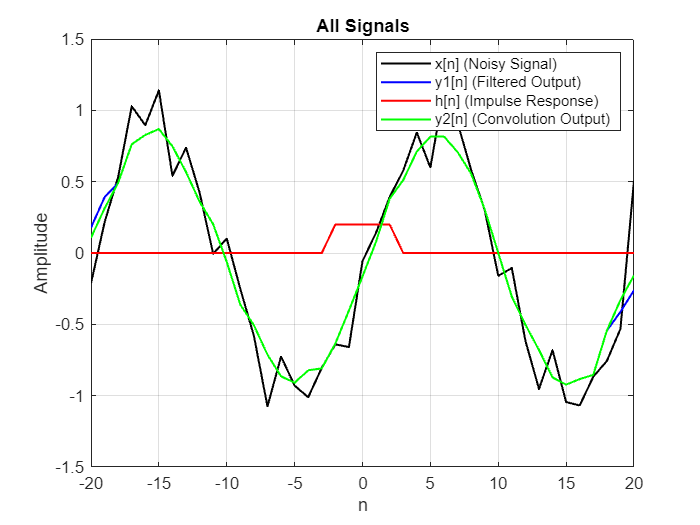

% Define the time range
n = -20:20;

%z[n]
z = sin(0.3142 * n);
%noise[n]
noise = 0.2 * randn(size(n));

x = z + noise; 
%Moving Average
y1 = movmean(x, 5);

delta = zeros(size(n));
delta(n == 0) = 1;  % Defining impulse signal δ[n]
h = movmean(delta, 5);

y2 = conv(x, h, 'same');

figure;
plot(n, x, 'k', 'LineWidth', 1.2); hold on;    
plot(n, y1, 'b', 'LineWidth', 1.2);            
plot(n, h, 'r', 'LineWidth', 1.2);             
plot(n, y2, 'g', 'LineWidth', 1.2);            
hold off;

% Labels and legends
xlabel('n');
ylabel('Amplitude');
title('All Signals');
legend('x[n] (Noisy Signal)', 'y1[n] (Filtered Output)', 'h[n] (Impulse Response)', 'y2[n] (Convolution Output)');
grid on;

#### Task 4

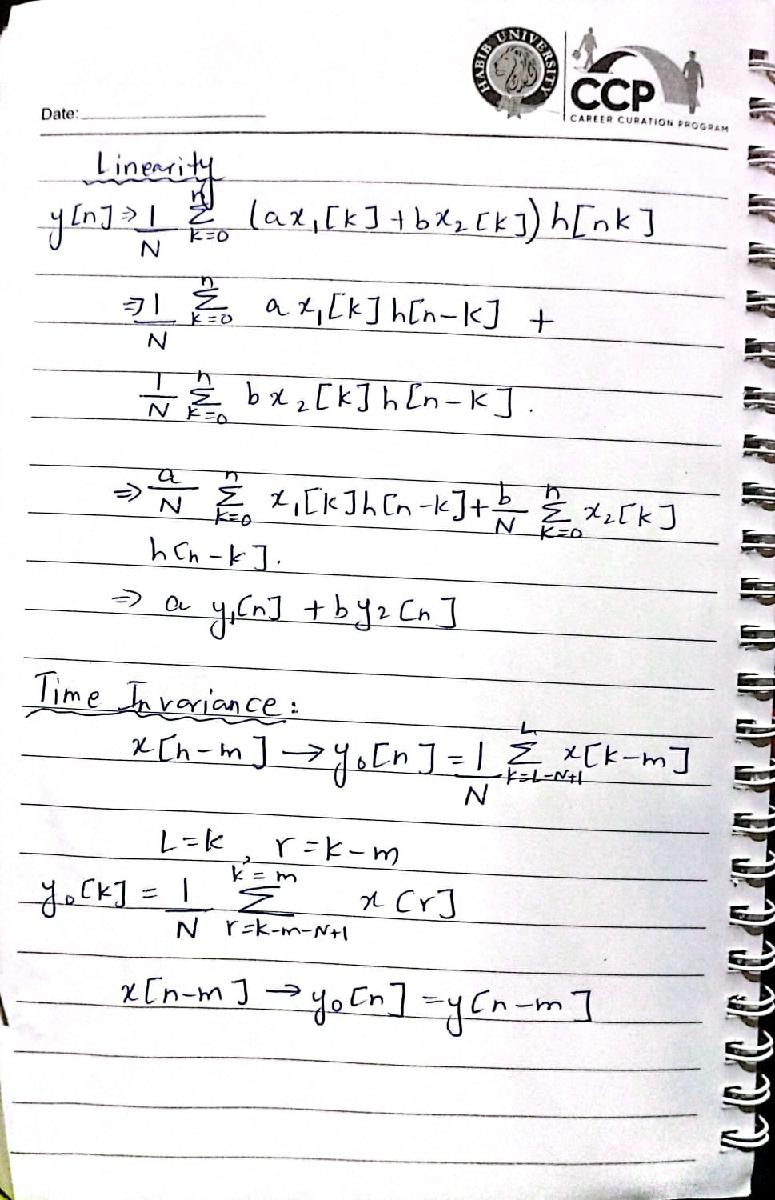

#### Task 5

[h, Fh] = audioread("1st_baptist_nashville_balcony.wav");
disp(size(h))

      288000           2




soundsc(h,Fh) % Play the sound
pause(length(h)/Fh) % Wait for audio to finish playing
[x, Fx] = audioread("ringtone.wav"); % Read input
disp(size(x))

      111616           1



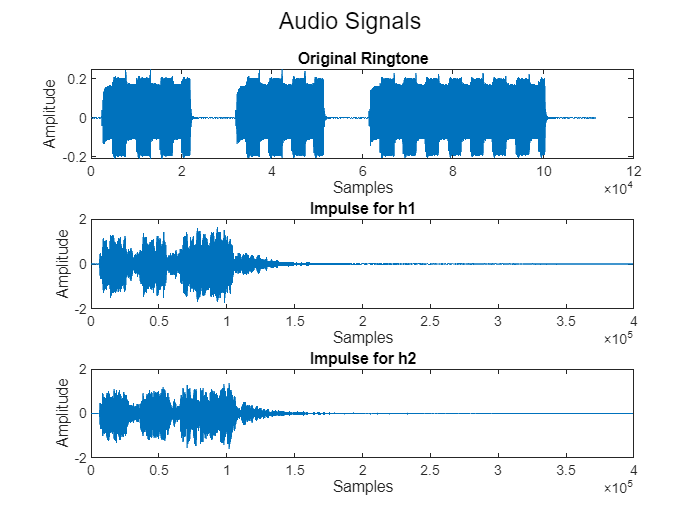


soundsc(x,Fx) % Play the sound

pause(length(x)/Fx) % Wait for audio to finish playing

h1 = h(:,1); % Extract the first channel from the impulse response

h2 = h(:,2); % Extract the second channel from the impulse respose

y1 = conv(x, h1);
y2 = conv(x, h2);

%Concatenate
y = [y1, y2];

soundsc(y, Fx);

% Step 7: Plot original and processed signals
figure;
subplot(3,1,1);
plot(x);
title('Original Ringtone');
xlabel('Samples');
ylabel('Amplitude');
subplot(3,1,2);

plot(y1);
title('Impulse for h1');
xlabel('Samples');
ylabel('Amplitude');

subplot(3,1,3);
plot(y2);
title('Impulse for h2');
xlabel('Samples');
 
ylabel('Amplitude');

sgtitle('Audio Signals');

#### Task 6

function w = discrete_convolution(u, v)
    % Lengths of input signals
    len1 = length(u);
    len2 = length(v);
    total = len1 + len2 - 1;
    
    % Reverse the second signal
    reversed_v = fliplr(v);
    
    % Initialize output vector
    w = zeros(1, total);
    
    % Compute convolution
    for b = 1:total
        convolution_sum = 0;
        % Determine valid indices for summation
        k_start = max(1, b - len2 + 1);
        k_end = min(b, len1);
        
        for k = k_start:k_end
            idx_v = b - k + 1;
            if idx_v >= 1 && idx_v <= len2
                convolution_sum = convolution_sum + u(k) * reversed_v(idx_v);
            end
        end
        w(b) = convolution_sum;
    end
end

h = [1, 2, 1];    
x = [1, 2, 3, 4, 5]; 
w_custom = discrete_convolution(x, h);

% Display convolution result
disp('Custom Convolution Output:')

Custom Convolution Output:


disp(w_custom)

     1     4     8    12    16    14     5



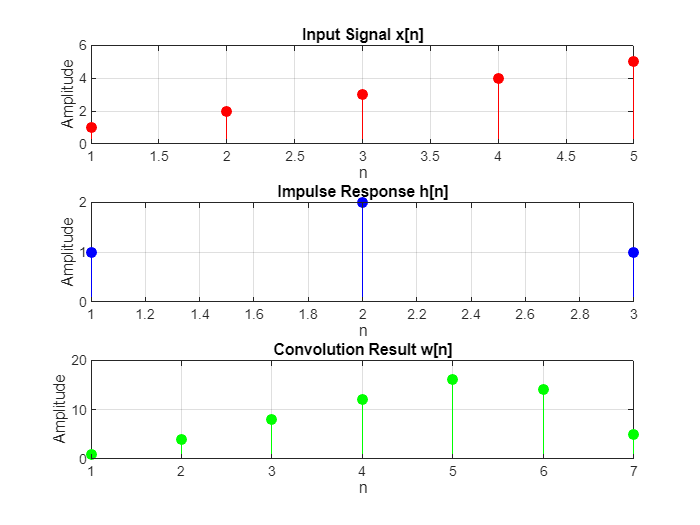


% Plotting
figure;

% Subplot 1: Input Signal x[n]
subplot(3,1,1);
stem(x, 'filled', 'r');
title('Input Signal x[n]');
xlabel('n');
ylabel('Amplitude');
grid on;

% Subplot 2: Impulse Response h[n]
subplot(3,1,2);
stem(h, 'filled', 'b');
title('Impulse Response h[n]');
xlabel('n');
ylabel('Amplitude');
grid on;

% Subplot 3: Convolution Result w[n]
subplot(3,1,3);
stem(w_custom, 'filled', 'g');
title('Convolution Result w[n]');
xlabel('n');
ylabel('Amplitude');
grid on;